# Trial 3: Asymptotic Efficiency under Different Noise Levels

clear;
close all;
clc;

## 1. Setting

### 1.1 Enviroment Setting

M=3; T=1000; % M*T1 anchors
N=2; % 2 tags
Room_Length=50; Room_Width=50; Robot_Size=5;
theta=60; R=[cosd(theta),-sind(theta);sind(theta),cosd(theta)];
t = [0;25];
[A,S,Mt]=setting(T,Room_Length,Room_Width,Robot_Size,M,N);

### 1.2 Simulation Settings

r10=sqrt(10);
sig=[0.01,0.1,1,10]; %standard deviations
L=500; %Monte-Carlo runs

%matrix to store simulation results
%ULS
Y0_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-ULS
Ye_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%MultiGN-ULS
Ym_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-SDP
Y1_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GTRS
Y2_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%Lower Bound
CRLB=zeros(length(T),2);

## 2. For different standard deviation of noises

for s=1:length(sig)
    sigma=sig(s);
    %mse
    mse_R0_c=0; mse_R0_a=0; mse_t0=0;
    mse_Re_c=0; mse_Re_a=0; mse_te=0;
    mse_Rm_c=0; mse_Rm_a=0; mse_tm=0;
    mse_R1_c=0; mse_R1_a=0; mse_t1=0;
    mse_R2_c=0; mse_R2_a=0; mse_t2=0;

    %true distance
    Sa=R*S+t; %tags' coordinate in global frame
    relative_position=zeros(2,Mt*N);
    for i=1:N %for every tag i=1,...,N
        relative_position(:,(i-1)*Mt+1:i*Mt)=A-Sa(:,i);
    end
    relative_distance=vecnorm(relative_position)'; %(Mt*N,1)

#### CRLB

    Sigma=sigma*ones(1,Mt*N); %standard deviations
    F=zeros(6,6);   %Fisher information
    for i=1:N       %for every tag i=1,...,N
        s_bar=[S(:,i);1];
        for m=1:Mt
            score=kron(s_bar,eye(2))*relative_position(:,(i-1)*Mt+m)/Sigma((i-1)*Mt+m)/relative_distance((i-1)*Mt+m);
            F=F+score*score';
        end
    end

#### ULS - precalculation  

    A_bar=A-(A*ones(Mt,1))*ones(1,Mt)/Mt;
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    H1=-2*kron(S',A_bar')*Psi;    %(N*Mt,2)
    H2=repmat(-2*A_bar',N,1); %(N*Mt,2)
    H=[H1,H2];       %(N*Mt,4)
    HtH_invHt=(H'*H)\H';

#### SDP- precalculation 

    c_norm = repmat((vecnorm(S))',Mt,1); %(Mt*N,1),||c||
    C=zeros(Mt*N,1);
    for i=1:N
        C((i-1)*Mt+1:i*Mt,:)=c_norm(i).^2;
    end

#### **GTRS**- precalculation 

    E1=zeros(Mt*N,2);
    E2=zeros(Mt*N,2);
    for i=1:N
        sigma_Mt=Sigma((i-1)*Mt+1:i*Mt); %standard deviation for range measurements of tag i
        %projection
        TAt= A'-ones(Mt,1)*((1./sigma_Mt.^2)*A')/(sum(1./sigma_Mt.^2));
        E1((i-1)*Mt+1:i*Mt,:)=-2*(kron(S(:,i)',TAt))*Psi; 
        E2((i-1)*Mt+1:i*Mt,:)=-2*TAt; 
    end

### 2.1 Monte-Carlo Runs

     for l=1:L
        d=relative_distance+Sigma'.*randn(Mt*N,1); %(Mt*N,1) distance measurements corrupted by Gaussian noises
        d_square=d.^2;

        %ULS
        tic;
        D=d_square-(vecnorm(repmat(A,1,N))').^2-(Sigma').^2;
        %projection
        for i=1:N
            D_bar((i-1)*Mt+1:i*Mt,:)= D((i-1)*Mt+1:i*Mt,:)-ones(Mt,1)*(ones(1,Mt)*D((i-1)*Mt+1:i*Mt,:))/Mt;
        end
        [R0,t0]= ULS(D_bar,HtH_invHt);

        %GN-ULS
        tic;
        [Re,te] = Gauss_Newton(R0,t0,A,S,d,Sigma);

        %multiGN-ULS
        tic;
        Rm=Re;
        tm=te;
        for k=1:10
            [Rm,tm]=Gauss_Newton(Rm,tm,A,S,d,Sigma);
        end

        %GN-SDP
        d1=d_square-(vecnorm(repmat(A,1,N))').^2-C;%(Mt*N,1)
        %       Rn=4*(d.*Sigma').^2+2*(Sigma').^4;
        Rn=4*(d.*Sigma').^2;  %ignore chi-squared random variable
        [R1,t1]= SDP(A,S,d1,Rn);
        [R1,t1]=Gauss_Newton(R1,t1,A,S,d,Sigma);

        %GTRS-first step
        DD=d_square-(vecnorm(repmat(A,1,N))').^2; %ignore the chi-squared random variable
        %projection
        for i=1:N
            sigma_Mt=Sigma((i-1)*Mt+1:i*Mt); %standard deviation for range measurements of tag i
            DD_bar((i-1)*Mt+1:i*Mt,:)=DD((i-1)*Mt+1:i*Mt,:)-ones(Mt,1)*( ((1./(sigma_Mt.^2))*DD((i-1)*Mt+1:i*Mt,:))/(sum(1./(sigma_Mt.^2))) );
        end

        [y20,t20]=GTRS(E1,E2,Rn,DD_bar,Mt,N);
        R20=[y20(2),-y20(1);y20(1),y20(2)];
        %GTRS-second step
        DDD=zeros(Mt*N,1);
        F1=zeros(Mt*N,2);
        F2=zeros(Mt*N,2);
        for i=1:N
            DDD((i-1)*Mt+1:i*Mt,:)=d_square((i-1)*Mt+1:i*Mt,:)-vecnorm(t20-A)'.^2-norm(S(:,i)).^2;
            F1((i-1)*Mt+1:i*Mt,:)=2*kron(S(:,i)',(t20-A)')*Psi;
            F2((i-1)*Mt+1:i*Mt,:)=2*(repmat(R20*S(:,i)+t20,1,Mt)'-A');
        end
        [y2,dt2]=GTRS(F1,F2,Rn,DDD,Mt,N);
        R2=[y2(2),-y2(1);y2(1),y2(2)];
        t2=t20+dt2;

        %MSE
        %ULS
        mse_R0_c=mse_R0_c+norm(R0-R,'fro')^2;
        mse_R0_a=mse_R0_a+angular_distance(R0,R)^2;
        mse_t0=mse_t0+norm(t0-t)^2;
        %GN-UCLS
        mse_Re_c=mse_Re_c+norm(Re-R,'fro')^2;
        mse_Re_a=mse_Re_a+angular_distance(Re,R)^2;
        mse_te=mse_te+norm(te-t)^2;
        %multiGN-ULS
        mse_Rm_c=mse_Rm_c+norm(Rm-R,'fro')^2;
        mse_Rm_a=mse_Rm_a+angular_distance(Rm,R)^2;
        mse_tm=mse_tm+norm(tm-t)^2;
        %GN-SDP
        mse_R1_c=mse_R1_c+norm(R1-R,'fro')^2;
        mse_R1_a=mse_R1_a+angular_distance(R1,R)^2;
        mse_t1=mse_t1+norm(t1-t)^2;
        %GTRS
        mse_R2_c=mse_R2_c+norm(R2-R,'fro')^2;
        mse_R2_a=mse_R2_a+angular_distance(R2,R)^2;
        mse_t2=mse_t2+norm(t2-t)^2;
        if mode(l,10)==0 %iteration tracking
            l
        end
     end

### 2.2 RMSE

    %ULS
    Y0_r(s,1)=sqrt(mse_R0_c/L);
    Y0_r(s,2)=sqrt(mse_R0_a/L);
    Y0_r(s,3)=sqrt(mse_t0/L);
    %GN-ULS
    Ye_r(s,1)=sqrt(mse_Re_c/L);
    Ye_r(s,2)=sqrt(mse_Re_a/L);
    Ye_r(s,3)=sqrt(mse_te/L);
    %GN-ULS
    Ym_r(s,1)=sqrt(mse_Rm_c/L);
    Ym_r(s,2)=sqrt(mse_Rm_a/L);
    Ym_r(s,3)=sqrt(mse_tm/L);
    %GN-SDP
    Y1_r(s,1)=sqrt(mse_R1_c/L);
    Y1_r(s,2)=sqrt(mse_R1_a/L);
    Y1_r(s,3)=sqrt(mse_t1/L);
    %GTRS
    Y2_r(s,1)=sqrt(mse_R2_c/L);
    Y2_r(s,2)=sqrt(mse_R2_a/L);
    Y2_r(s,3)=sqrt(mse_t2/L);

### 2.3 Constrained Cramer Rao Lower Bound

    CR=constrained_CRB(F,R);
    CRLB(s,1)=sqrt(sum(diag(CR(1:4,1:4))));
    CRLB(s,2)=sqrt(sum(diag(CR(5:6,5:6))));
    s
end

s = 1

s = 2

s = 3

s = 4

% save('Trial3_plot.mat','sig','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB')

## 3. Plot

### 3.1 RMSE and noise variance

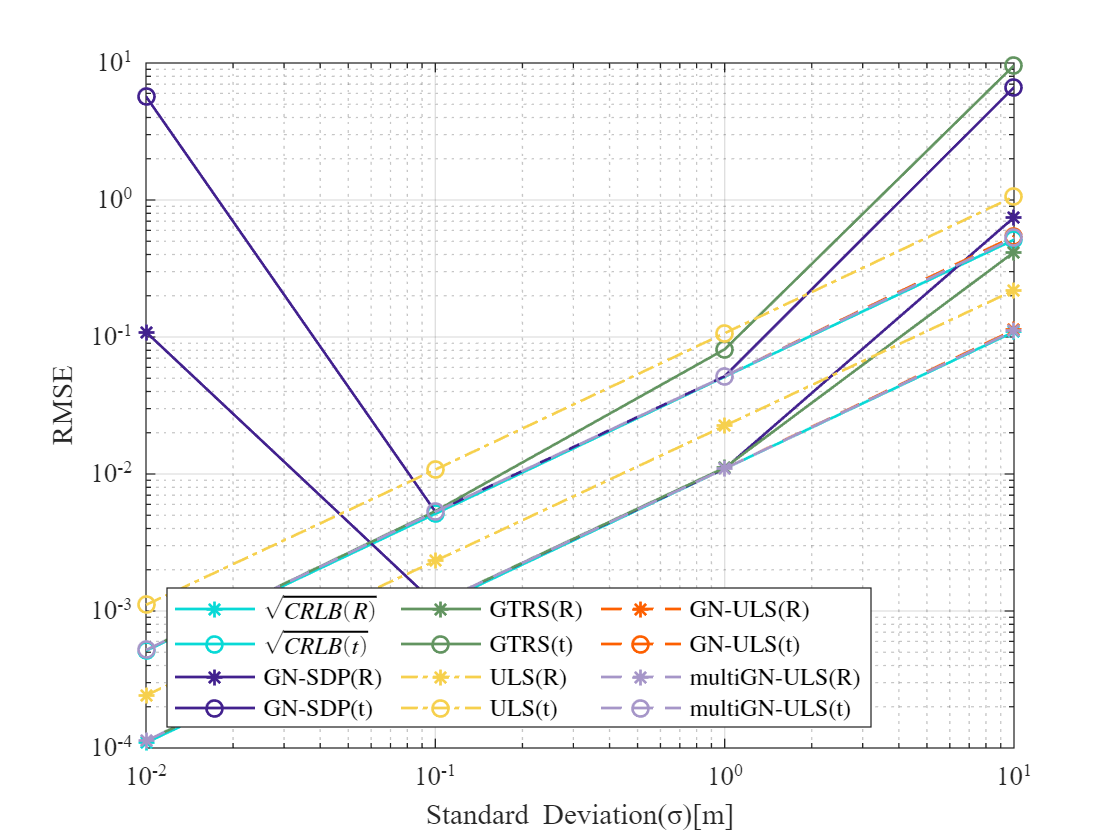

figure(1)
%CRLB
loglog(sig,CRLB(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#08D9D6');
hold on
loglog(sig,CRLB(:,2),'-o','LineWidth',1,'MarkerSize',6,'Color','#08D9D6');
hold on
%GN-SDP
loglog(sig,Y1_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
loglog(sig,Y1_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
%GTRS
loglog(sig,Y2_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
loglog(sig,Y2_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
%ULS
loglog(sig,Y0_r(:,1),'-.*','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
loglog(sig,Y0_r(:,3),'-.o','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
%GN-ULS
loglog(sig,Ye_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
loglog(sig,Ye_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
%multiGN-ULS
loglog(sig,Ym_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#a696c8');
hold on
loglog(sig,Ym_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#a696c8');
hold off

set(gca,'Fontname', 'Times New Roman')
xlabel('Standard Deviation(\sigma)[m]')
ylabel('RMSE')
lgd=legend({'$$\sqrt{CRLB(R)}$$','$$\sqrt{CRLB(t)}$$','GN-SDP(R)','GN-SDP(t)','GTRS(R)','GTRS(t)', ...
    'ULS(R)','ULS(t)','GN-ULS(R)','GN-ULS(t)','multiGN-ULS(R)','multiGN-ULS(t)'}, ...
    'interpreter','latex','Location','southwest');
lgd.NumColumns=3;
grid on